% xtime = seconds(WF{:,1});
% S = table2timetable(WF,"RowTimes",xtime);
% S(:,1) = [];

% xtime = seconds(WF.Temps(:));
% x3 = seconds(WF{:,1});
% WFTime = table2timetable(WF,"RowTimes",xtime);
% WFTime.Temps = [];
% pspectrum(WFTime.("1_1"),xtime,"spectrogram");

moy = 0;
moytot = 0;
WF{end,:} = 0;
l = size(WF);
Fs = -1/(WF.Temps(1)-WF.Temps(2)); % Freq d'échantillonage en Hz

for i=1:l(2)
    X = WF{:,i};
    Y = [X zeros(l(1),1)];
%     X = lowpass(X,1e6,Fs);
    moytot = moytot+fft(X);
    moy = moy+fft(Y(1:2:end)); 
end
moytot = moytot/l(2);
moy = moy/(2*l(2));
lim = 2.5;

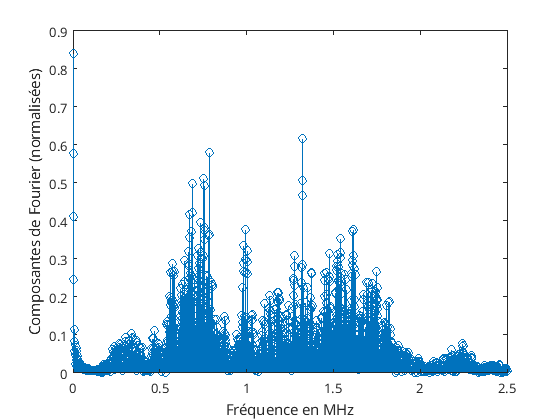

figure();
Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(2))); % Freq d'échantillonage en Hz
Te = 1/Fs;
N = l(1);
freq = [0:N-1]/(N*Te);
stem(freq/Te,abs(moytot));%stem est un type de plot souvent utilisé pour représenter les spectres
xlabel('Fréquence en MHz');
ylabel('Composantes de Fourier (normalisées)');
xlim([0 lim]);

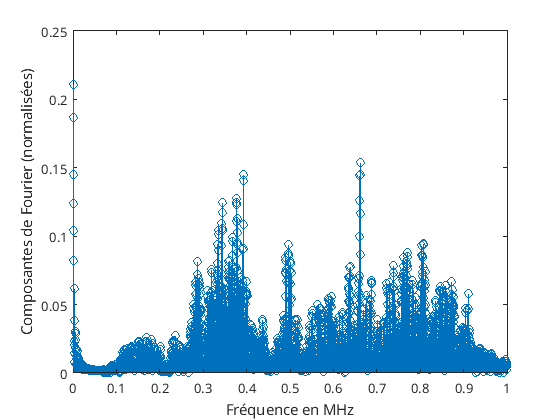

figure();
Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(3))); % Freq d'échantillonage en Hz
Te = 1/Fs;
N = fix(l(1));
freq = [0:N-1]/(N*Te);
stem(freq/Te,abs(moy));
xlabel('Fréquence en MHz');
ylabel('Composantes de Fourier (normalisées)');
xlim([0 lim/2.5]);



figure();
Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(2))); % Freq d'échantillonage en Hz
Te = 1/Fs;
N = l(1);
freq = [0:N-1]/(N*Te);
plot(freq/Te,20*log10(moytot));%stem est un type de plot souvent utilisé pour représenter les spectres

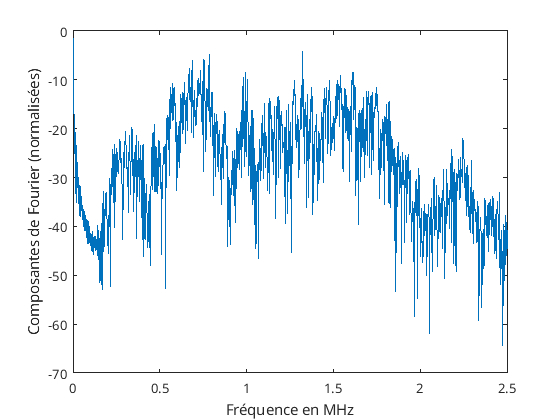

xlabel('Fréquence en MHz');
ylabel('Composantes de Fourier (normalisées)');
xlim([0 lim]);

figure();
Fs = -1/(1000000*(WF.Temps(1)-WF.Temps(3))); % Freq d'échantillonage en Hz
Te = 1/Fs;
N = fix(l(1));
freq = [0:N-1]/(N*Te);
plot(freq/Te,20*log10(moy));%stem est un type de plot souvent utilisé pour représenter les spectres

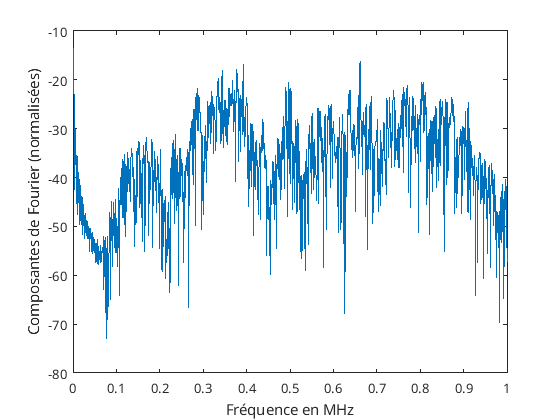

xlabel('Fréquence en MHz');
ylabel('Composantes de Fourier (normalisées)');
xlim([0 lim/2.5]);